# MOSFET Characteristics Response Parametrization

[-> go back to starting page](matlab:open('./StartingPage.mlx'))

## **MOSFET to be modeled**

Examine datasheet of MOSFET:

[https://www.onsemi.com/pdf/datasheet/fdpf20n50ft-d.pdf](https://www.onsemi.com/pdf/datasheet/fdpf20n50ft-d.pdf)

FDP20N50F / FDPF20N50FT

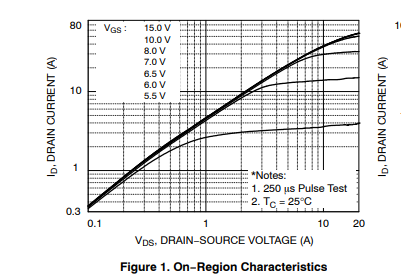

## Load model

mdlName = 'MOSFET_Characteristics_Generation';
open_system(mdlName);

## Simulate testcase

The code below instrument and perform simulation for a range of gate voltages, based on the Id vs Vds plot of the desired MOSFET type (see datasheet screenshot above).

Vg_vec = [5.5 6 6.5 7 8 10 15]';% V
Vg = 10;
Vds_min = 0.1;% V
Vds_max = 20; % V
Id_min = 0.3; % A
Id_max = 80;  % A
t_sim = 1;    % s


Create simulation input object for the various Vg

simIn(1:length(Vg_vec)) = Simulink.SimulationInput(mdlName);

for i=1:length(Vg_vec)
    simIn(i) = setVariable(simIn(i),'Vg',Vg_vec(i));
    legend_info{i} = ['Vg = ',num2str( Vg_vec(i))];
end

Simulate

out = sim(simIn,"UseFastRestart","on");

[02-Oct-2024 14:17:12] Running simulations...
[02-Oct-2024 14:17:15] Completed 1 of 7 simulation runs
[02-Oct-2024 14:17:15] Completed 2 of 7 simulation runs
[02-Oct-2024 14:17:15] Completed 3 of 7 simulation runs
[02-Oct-2024 14:17:16] Completed 4 of 7 simulation runs
[02-Oct-2024 14:17:16] Completed 5 of 7 simulation runs
[02-Oct-2024 14:17:16] Completed 6 of 7 simulation runs
[02-Oct-2024 14:17:17] Completed 7 of 7 simulation runs


Plot results:

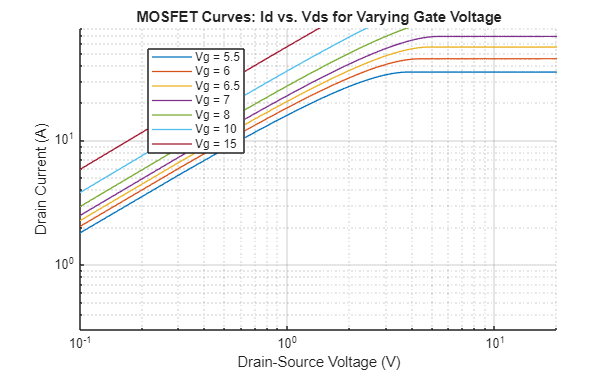

customPlotSemiconductorResults(Vg_vec,out,Vds_min,Vds_max,Id_min,Id_max,legend_info);

The default values of the MOSFET in the model obviously do not match with the datasheet of the desired model. Let's simulate a model preprepared with values taken from the datasheet:

R_DS = 0.22;%Ohm
Ids = 10; %A
Vgs = 10; %V
Vth = 4; %V (min 3 max 5)
Tmeas = 25; % °C
Ciss = 2550; %pF
Coss = 350;%pF
Crss = 27;%pF

mdlName = 'MOSFET_Characteristics_Generation_datasheet';
open_system(mdlName);

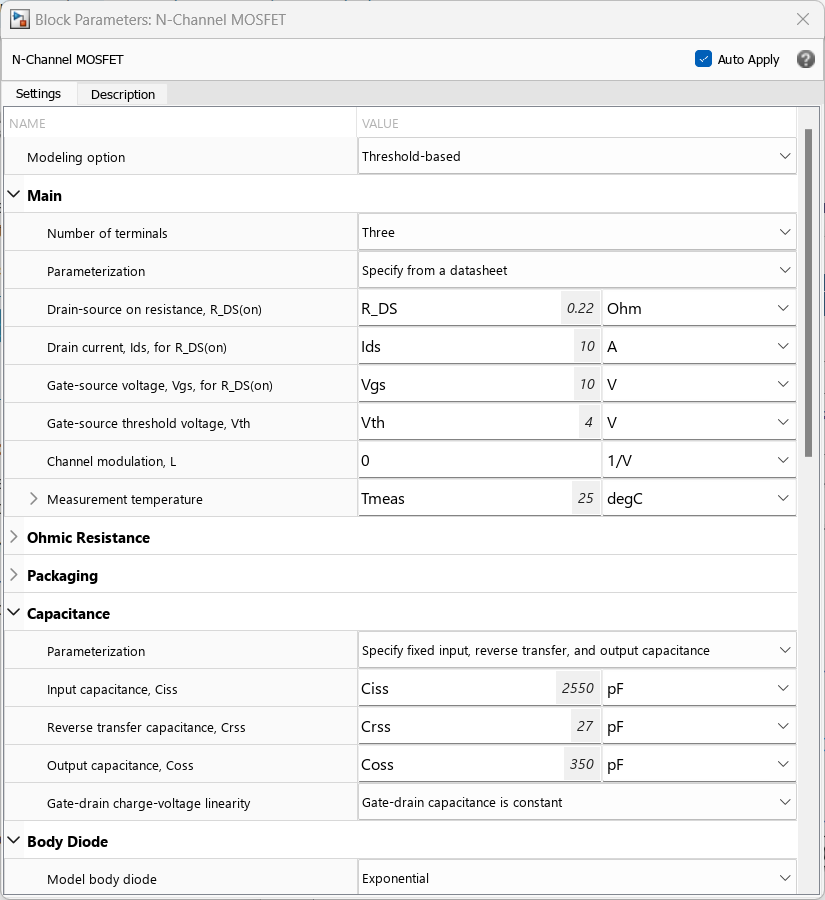

Performing the same test:

simIn(1:length(Vg_vec)) = Simulink.SimulationInput(mdlName);

for i=1:length(Vg_vec)
    simIn(i) = setVariable(simIn(i),'Vg',Vg_vec(i));
    legend_info{i} = ['Vg = ',num2str( Vg_vec(i))];
end

Simulate

out = sim(simIn,"UseFastRestart","on");

[02-Oct-2024 14:17:21] Running simulations...
[02-Oct-2024 14:17:23] Completed 1 of 7 simulation runs
[02-Oct-2024 14:17:24] Completed 2 of 7 simulation runs
[02-Oct-2024 14:17:24] Completed 3 of 7 simulation runs
[02-Oct-2024 14:17:24] Completed 4 of 7 simulation runs
[02-Oct-2024 14:17:25] Completed 5 of 7 simulation runs
[02-Oct-2024 14:17:25] Completed 6 of 7 simulation runs
[02-Oct-2024 14:17:26] Completed 7 of 7 simulation runs


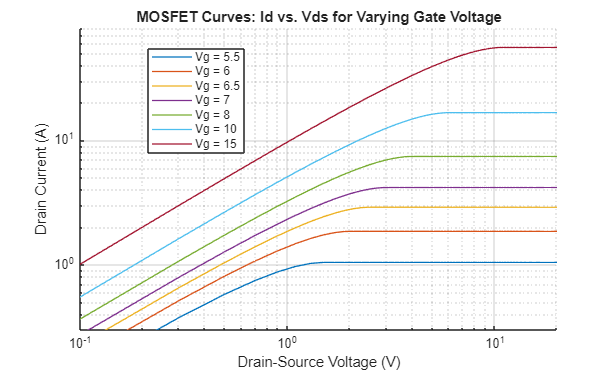

customPlotSemiconductorResults(Vg_vec,out,Vds_min,Vds_max,Id_min,Id_max,legend_info);

These results are slightly better for very little work, just copying a couple of parameters from the datasheets. Better results could be obtained by tabulating the plot in the datasheets and use these tabulated information directly.

To obtain the tabulated values, is possible to use the Graph Importer App:

graphImporter

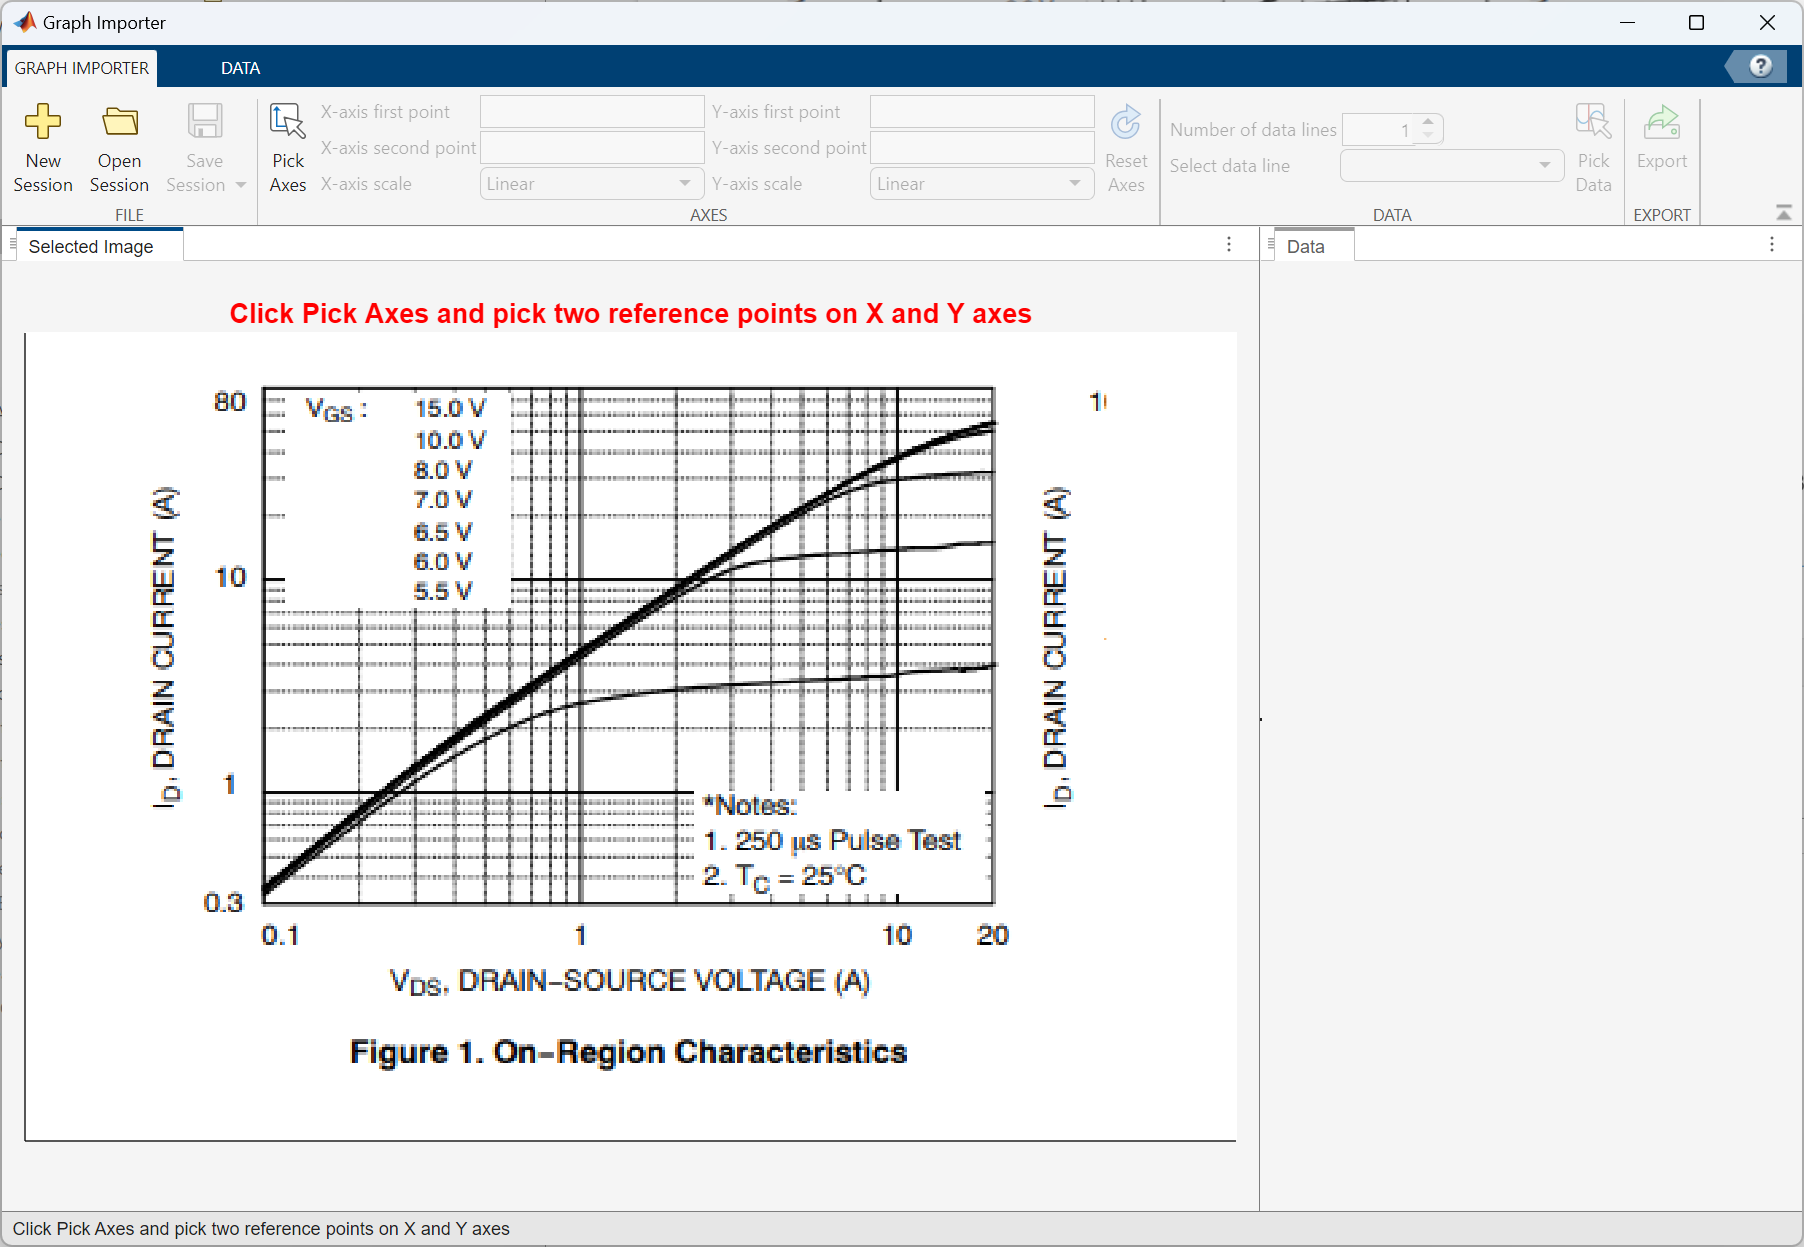

This is the exported data, a variable named tableData

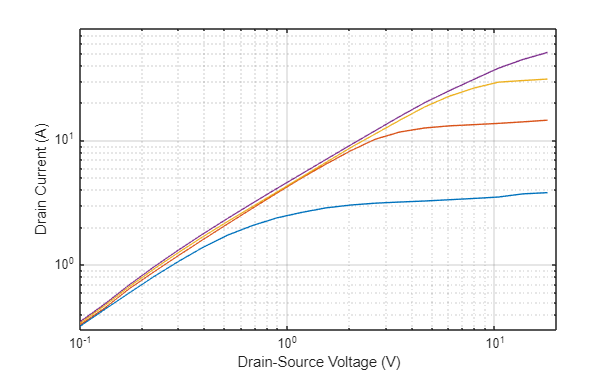

load MOSFET_FDPF20N50FT_GraphImporterData
h = figure;
plot(tableData(:,1),tableData(:,2:5))
axis([Vds_min Vds_max Id_min Id_max]);
xlabel('Drain-Source Voltage (V)');
ylabel('Drain Current (A)');
grid on
yscale log
xscale log

This data is a replica in MATLAB of the screenshot, is not (yet) the new MOSFET response simulation. We can see that we imported the graph quite well:

Let's use the vector grabbed from the picture in the MOSFET block. This time we use the Table interpolated parametrization option:

mdlName = 'MOSFET_Characteristics_Generation_tabulated';
open_system(mdlName);

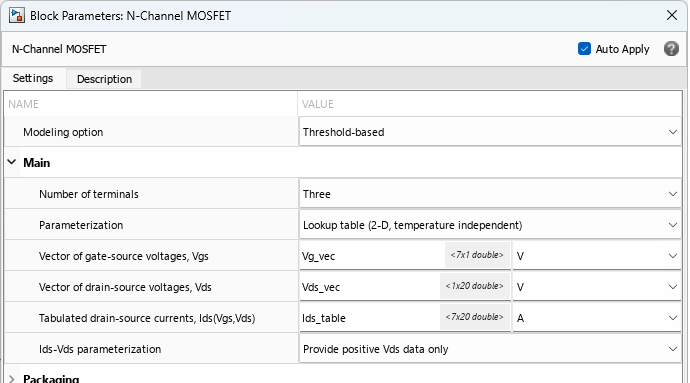

we need to adapt the table data. for the region of interest, we can replicate the last column since the curves in the datasheets for Vg = 7,8,10 and 15 V are all very similar:

Vds_vec=tableData(:,1)';
Ids_table = [tableData(:,2:5) tableData(:,5) tableData(:,5) tableData(:,5)]';

Performing the same test:

simIn(1:length(Vg_vec)) = Simulink.SimulationInput(mdlName);

for i=1:length(Vg_vec)
    simIn(i) = setVariable(simIn(i),'Vg',Vg_vec(i));
    legend_info{i} = ['Vg = ',num2str( Vg_vec(i))];
end

Simulate

out = sim(simIn,"UseFastRestart","on");

[02-Oct-2024 14:17:31] Running simulations...


[02-Oct-2024 14:17:35] Completed 1 of 7 simulation runs
[02-Oct-2024 14:17:36] Completed 2 of 7 simulation runs
[02-Oct-2024 14:17:37] Completed 3 of 7 simulation runs
[02-Oct-2024 14:17:37] Completed 4 of 7 simulation runs
[02-Oct-2024 14:17:38] Completed 5 of 7 simulation runs
[02-Oct-2024 14:17:38] Completed 6 of 7 simulation runs
[02-Oct-2024 14:17:39] Completed 7 of 7 simulation runs


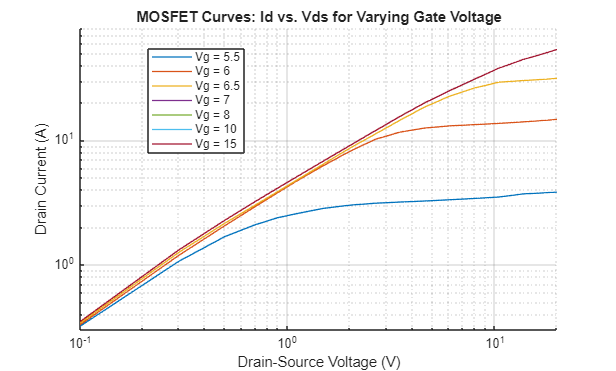

customPlotSemiconductorResults(Vg_vec,out,Vds_min,Vds_max,Id_min,Id_max,legend_info);

This are now the results of the simulation and of course is a great fit to the datasheet:

## Diode Parametrization

We can do the same for the internal diode and parametrize it using this datasheet plot:

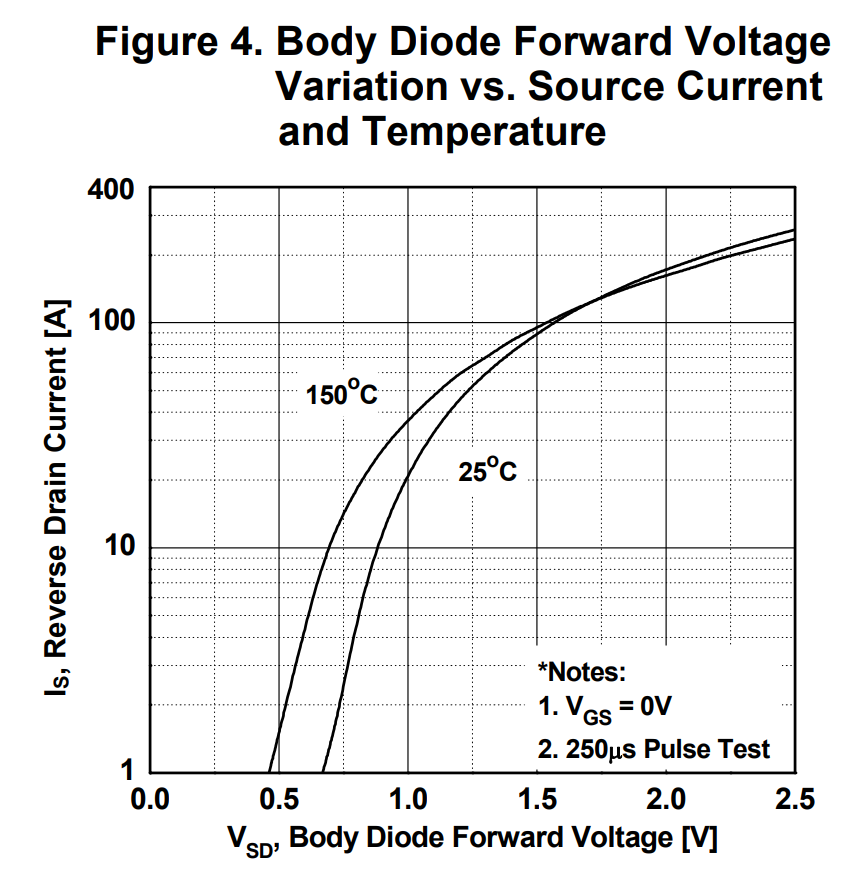

After importing he data with graphImporter (data for 25°C):

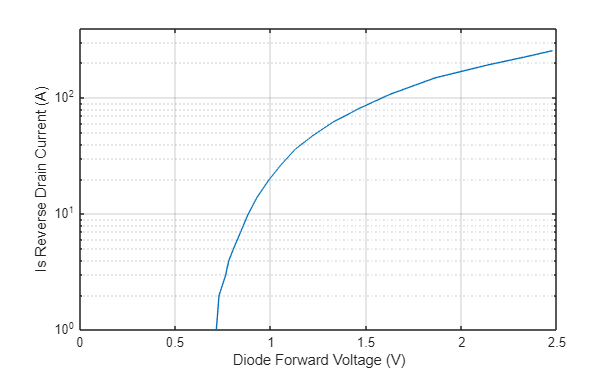

load MOSFET_Diode_FDPF20N50FT_GraphImporterData
h = figure;
plot(tableDataDiode(:,1),tableDataDiode(:,2))
axis([0 2.5 1 400]);
xlabel('Diode Forward Voltage (V)');
ylabel('Is Reverse Drain Current (A)');
grid on
yscale log

We need now to create an interpolated array and use it to parametrize the diode:

mdlName = "MOSFET_Diode_Characteristics_Generation_tabulated";
open_system(mdlName);
Vf_vec = tableDataDiode(:,1)';
If_vec = tableDataDiode(:,2)';

Simulation and comparison:

out = sim(mdlName);

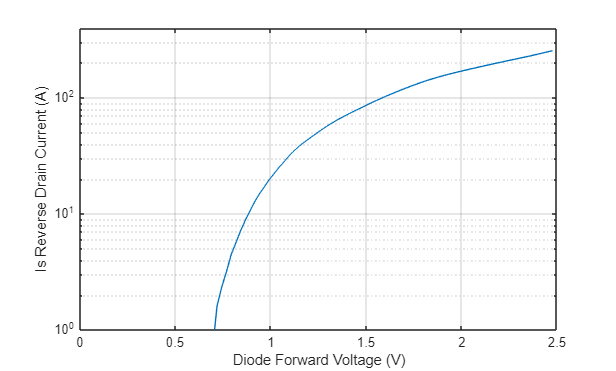

plot(out.logsout_MOSFETCharacteristics{2}.Values.Data,out.logsout_MOSFETCharacteristics{1}.Values.Data)
axis([0 2.5 1 400]);
xlabel('Diode Forward Voltage (V)');
ylabel('Is Reverse Drain Current (A)');
grid on
yscale log

#### [-> go back to starting page](matlab:open('./StartingPage.mlx'))

#### Cleanup

bdclose all
clear out simIn Ids_table Vds_vec h Vf_vec If_vec Crss Coss Ciss Tmeas Vth Vg legend_info Id_max Id_min Vds_max Vds_min Vg_vec mdlName tableData Ids R_DS t_sim Vgs

*$Copyright 2008-2023 The MathWorks, Inc.*